Load and clean the dataset 

% The dataset is loaded as ds
ds = readtable("breast_cancer_data.csv")

ds = 569×32 table
       Var1       Var2     Var3     Var4     Var5     Var6      Var7       Var8       Var9       Var10     Var11      Var12     Var13     Var14     Var15    Var16     Var17       Var18       Var19      Var20       Var21      Var22      Var23    Var24    Var25    Var26    Var27     Var28     Var29      Var30     Var31      Var32 
    __________    _____    _____    _____


% the variables in the Table are renamed instead of being called var+num
ds.Properties.VariableNames = ["id", "diagnosis", "radius_mean", "texture_mean", "perimeter_mean", "area_mean", "smoothness_mean", "compactness_mean", "concavity_mean", "concave_points_mean", "symmetry_mean", "fractal_dimension_mean", "radius_se", "texture_se", "perimeter_se", "area_se", "smoothness_se", "compactness_se", "concavity_se", "concavity_point_se", "symmetry_se", "fractal_dimension_se","radius_worst","texture_worst","perimeter_worst","area_worst","smoothness_worst","compactness_worst","concavity_worst","concave_point_worst","symmetry_worst","fractal_dimension_worst"];

% Check for missing values in the entire matrix
nanValuesds = ismissing(ds);

% Display the logical matrix of missing values
disp('Logical matrix of NaN values:');

Logical matrix of NaN values:


disp(nanValuesds);

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 


% No missing values were found in the entire dataset

Exploratory Data Analysis

% Display the shape of the data
dsshape = size(ds)

dsshape =    569    32



% Display the unique values of the diagnosis column
diagnosis_unique = unique(ds.diagnosis)

diagnosis_unique = 2×1 cell array
    {'B'}
    {'M'}



% Describe the data
summary(ds)

Variables:

    id: 569×1 double

        Values:

            Min             8670
            Median    9.0602e+05
            Max       9.1132e+08

    diagnosis: 569×1 cell array of character vectors

    radius_mean: 569×1 double

        Values:

            Min        6.981  
            Median     13.37  
            Max        28.11  

    texture_mean: 569×1 double

        Values:

            Min         9.71  
            Median     18.84  
            Max        39.28  

    perimeter_mean: 569×1 double

        Values:

            Min        43.79  
            Median     86.24  
            Max        188.5  

    area_mean: 569×1 double

        Values:

            Min        143.5  
            Median     551.1  
            Max         2501  

    smoothness_mean: 569×1 double

        Values:

            Min       0.05263 
            Median    0

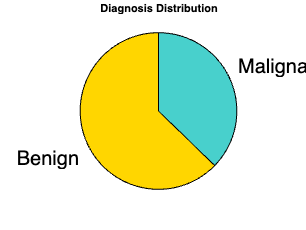

%____________________________________________
% Check how what the distribution of the target is

benign_count = 357 ; 
malignant_count = 212 ;

% Data for the pie chart
data = [benign_count, malignant_count];

% Labels for the pie chart
labels = {'Benign', 'Malignant'};

% Create the pie chart
figure;
p = pie(data, labels);

% Color settings (gold and medium turquoise)
colors = [1, 0.8431, 0; 0.2824, 0.8196, 0.8];
colormap(colors);

% Enhance text properties
txt = findobj(p, 'Type', 'text');
set(txt, 'FontSize', 20);

% Display the figure
title('Diagnosis Distribution');

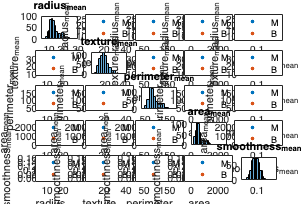


%__________________________________________________
% selected joint and marginal feature distributions

% Assuming 'id' is the first column and you want to exclude it,
% extract the next six columns of data
data_six = ds{:, 3:7};

% Extract the variable names for the selected columns
variableNames = ds.Properties.VariableNames(3:7);

% Assuming 'diagnosis' is a categorical variable in your table
categories = ds.diagnosis;

% Number of variables
numVars = size(data_six, 2);

% Create figure
figure;

% Loop through all combinations of variables
for i = 1:numVars
    for j = 1:numVars
        % Create subplot
        ax = subplot(numVars, numVars, (i-1) * numVars + j);

        if i == j
            % Plot histogram on the diagonal
            histogram(ax, data_six(:,i));
            title(ax, variableNames{i}); % Use variable name as title for diagonal
        else
            % Plot scatter plot for off-diagonal
            gscatter(ax, data_six(:,j), data_six(:,i), categories);
            xlabel(ax, variableNames{j}); % Set x-axis label
            ylabel(ax, variableNames{i}); % Set y-axis label
        end
    end
end

% Improve spacing between subplots
set(gcf, 'Position', [100, 100, 1200, 800]); % Resize figure

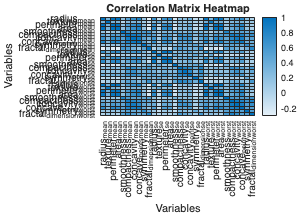


%__________________________________________________
% correlation matrix 

% Calculate the correlation matrix
corrMatrix = corr(ds{:, 3:end}); % Excludes the first column which is 'ID'.

% Create a heatmap
figure;
h = heatmap(corrMatrix);

% Set the x and y labels
h.XDisplayLabels = ds.Properties.VariableNames(3:end);
h.YDisplayLabels = ds.Properties.VariableNames(3:end);

% Optional: Customize the heatmap
h.CellLabelFormat = '%.2f';
h.XLabel = 'Variables';
h.YLabel = 'Variables';
h.Title = 'Correlation Matrix Heatmap';

% Customize the figure size
set(gcf, 'Position', [100, 100, 1000, 700]); % Resize figure

Data preprocessing

% first encode labels where benign will be represented as 0 and malignant
% will be represented as 1

% 'diagnosis' column is converted to a categorical array
ds.diagnosis = categorical(ds.diagnosis);

% Obtain unique categories (assuming 'B' and 'M')
categories = unique(ds.diagnosis);

% Encode the categories numerically
% 'B' is encoded as 0 and 'M' is encoded as 1
numericLabels = double(ds.diagnosis == 'M');

% Add the numeric labels to the 'diagnosis' column
ds.diagnosis = numericLabels;

% Count the occurrences of each unique value
countM = sum(ds.diagnosis == 1); % Count of 'M'
countB = sum(ds.diagnosis == 0); % Count of 'B'

% Display the counts
fprintf('Count of M: %d\n', countM);

Count of M: 212


fprintf('Count of B: %d\n', countB);

Count of B: 357



%______________________________________________________
% Second, the data is split into training and testing sets

% Random seed is et to make code reproduceable.
rng(42);  
% Start extracting the features and labels
X = ds{:, 2:end};  % All columns except the first which consists of id and won't be of use
y = ds.diagnosis;  % label/class column

% Determine the size of the dataset
numRows = size(X, 1);

% Number of test samples (20% of the dataset)
numTestSamples = floor(0.2 * numRows);

% Generate random indices
indices = randperm(numRows);

% the data is split 80:20 to training and testing sets
X_train = X(indices(numTestSamples+1:end), :);
y_train = y(indices(numTestSamples+1:end));
X_test = X(indices(1:numTestSamples), :);
y_test = y(indices(1:numTestSamples));

Feature Engineering 

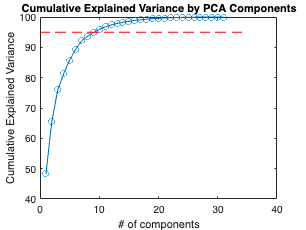

% Implement a scaler

% Calculate the median and IQR for X_train
median_X_train = median(X_train);
iqr_X_train = iqr(X_train);

% Apply the robust scaling to X_train
% Subtract the median and divide by the IQR
X_train = (X_train - median_X_train) ./ iqr_X_train;

% Apply the same transformation to X_test
X_test = (X_test - median_X_train) ./ iqr_X_train;

%________________________________________________
% Perform PCA
[coeff, score, latent, tsquared, explained] = pca(X_train);

% Calculate cumulative explained variance
cumulativeExplained = cumsum(explained);

% Plot the cumulative explained variance
figure;
plot(1:length(cumulativeExplained), cumulativeExplained, '-o');
xlabel('# of components');
ylabel('Cumulative Explained Variance');
title('Cumulative Explained Variance by PCA Components');

% Add a line at a specific explained variance, e.g., 95%
hold on;
line(xlim, [95 95], 'Color', 'r', 'LineStyle', '--');
hold off;

Model implementation and evaluation

% Logistic Regression (LR model) 
[bestParams, bestScore] = tuneLogisticRegression(X_train, y_train);

The best parameters for the classifier are:
         C: 100
    Lambda: 0.0100

The best training score is: 0.991


Accuracy=0.991
Sensitivity=0.979
Specificity=1.000
Precision=1.000
F-measure=0.989


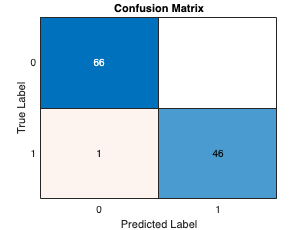

Accuracy = 0.9912

Sensitivity = 0.9787

Specificity = 1

Precision = 1

F_measure = 0.9892

% The logistic regression model is trained using the best hyperparameters
% which were obtained using the TuneLogisticRegression fn
logRegModel = fitclinear(X_train, y_train, 'Learner', 'logistic', 'Lambda', bestParams.Lambda);
% Display and calculate the performance metrics of the model on the test
% set after being trained
[Accuracy, Sensitivity, Specificity, Precision, F_measure] = metrics(X_test, y_test, logRegModel)

%_____________________________________________________________________________
%Random Forest (RF model)
[bestParams, bestScore] = tuneRandomForest(X_train, y_train);

The best parameters for the classifier are:
    n_estimators: 20
       criterion: 'gdi'
       bootstrap: 1

The best out-of-bag score is: 0.719


Accuracy=1.000
Sensitivity=1.000
Specificity=1.000
Precision=1.000
F-measure=1.000


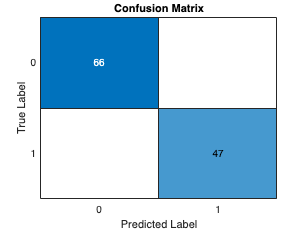

Accuracy = 1

Sensitivity = 1

Specificity = 1

Precision = 1

F_measure = 1


% Train the Random Forest model with the best parameters which were
% obtained using the TuneRandomForest fn
rfModel = TreeBagger(bestParams.n_estimators, X_train, y_train, 'SplitCriterion',bestParams.criterion);
% Calculate the metrics for the test set using the trained model
[Accuracy, Sensitivity, Specificity, Precision, F_measure] = metrics(X_test, y_test, rfModel)